# EE 521 Newton Raphson Power Flow

#### `README`

`Make sure to set MATLAB's working directory as the location of ee521_powerFlow.mlx`

`Currently the NRPF algorithm does NOT support bus type conversion. This obviously affects convergence for bigger bus systems, but fortunately does not seem to affect the 14 and 30 bus systems.`

`Currently it converges for the 14 and 30 bus systems, has trouble with 57 bus system for a couple of buses and blows up for the 118 bus system. I have added another small 3 bus system called koth3 (from Kothari and Nagrath's Modern Power System Analysis) for sanity checks, which converges.`

$N$` bus systems with individual bus numbers `$i$` outside `$[1, N]$`, `$i \in \mathbb{N}$` are currently NOT supported. The ieee300 bus system is one such system.`

### Preamble and Control Inputs

tic;
addpath functions\ %all functions are stored in this folder.
% ieee300 removed from systemName variable options due to poor compatibility. 
% Current algorithm does NOT support N bus systems with bus numbers outside of natural numbers 1 to N.
systemName = "ieee14"; 
powerFlowMethod =  "NRPF" 

powerFlowMethod = "NRPF"

numIterations = 50; %I don't wait for the system to converge, 
% neither do I care if the system converges earlier.
toleranceLimit = 1e-5; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayTables = false; %show busData, branchData, ybus, 
% basically data structures which are not the final output.
printJacobians = true; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = true; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
reducedBranchColumnsCDFReading = true; %Don't read last few branchData columns in CDF files 
% as they are NOT consistent between different CDF files and may cause error in this program.
% (NOTE: Power Flow NOT affected in any way by checking this option.)
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system

% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranch] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);
if displayTables
    busData
    branchData
    N
    numBranch
end

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table.`

if strcmp(powerFlowMethod, 'NRPF') || strcmp(powerFlowMethod, 'Decoupled NRPF')
    [ybus, ~, ~, ~, ~, E] = ybusGenerator(busData, branchData, N, numBranch, disableTaps);
elseif strcmp(powerFlowMethod, 'DC Power Flow')
    [ybus, BMatrix, b, A, branchNames, E] = ybusGenerator(busData, branchData, N, numBranch, disableTaps);
elseif strcmp(powerFlowMethod, 'Fast Decoupled NRPF')
%     [~, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData, N, numBranch, disableTaps);
%     ybus = BMatrix;
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData, N, numBranch, disableTaps);
%     ybus = imag(ybus);
end

if displayTables
    ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)]) %#ok<UNRCH> 
    if strcmp(powerFlowMethod, 'DC Power Flow')
        BMatrixTable = array2table(BMatrix, VariableNames=[string(1:N)], RowNames=[string(1:N)])
        ATable = array2table(A, VariableNames=[string(1:N)], RowNames=branchNames)
        bTable = array2table(b, VariableNames=branchNames, RowNames=branchNames)
    end
end

### Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[PSpecified, QSpecified, V, delta, ...
    listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
    listOfNonSlackBuses] = initializeVectors(busData, N, MVAb);


[P, Q, V, delta] = solveForPowerFlow(...
    PSpecified, QSpecified, V, delta, ...
    ybus, BMatrix, E, N, nPQ, nPV, ...
    listOfPQBuses, listOfNonSlackBuses, ...
    numIterations, toleranceLimit, powerFlowMethod, ...
    displayTables, printJacobians, printMismatches);

Convergence still not achieved in 1 iterations as 0.152840 is greater than 0.000010
Convergence still not achieved in 2 iterations as 0.004179 is greater than 0.000010
Convergence still not achieved in 3 iterations as 0.000045 is greater than 0.000010
Convergence using NRPF achieved in 4 iterations.


### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

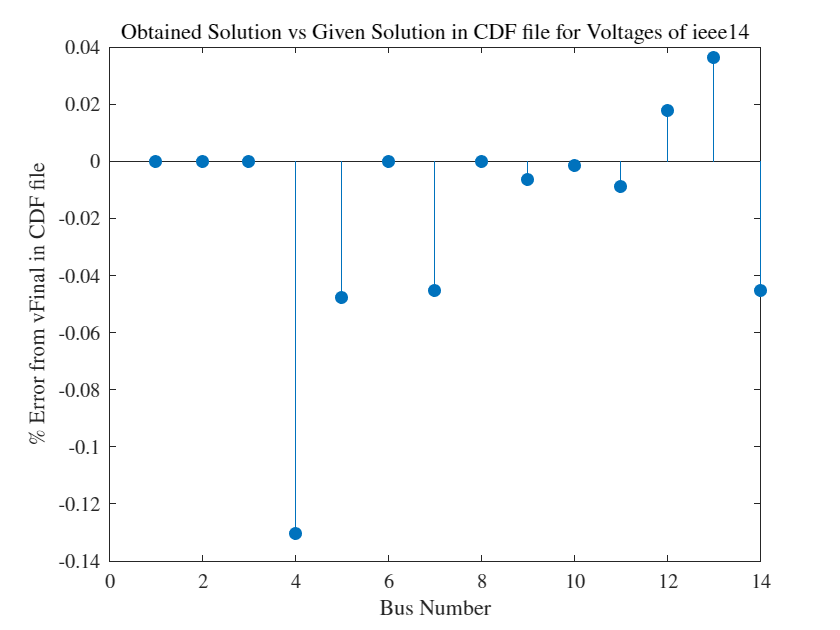

voltagePercentageError = ((V-busData.vFinal)./busData.vFinal)*100;
stem(voltagePercentageError, 'filled');
xlabel('Bus Number');
ylabel('$\%$ Error from vFinal in CDF file');
title('Obtained Solution vs Given Solution in CDF file for Voltages of ' + systemName);

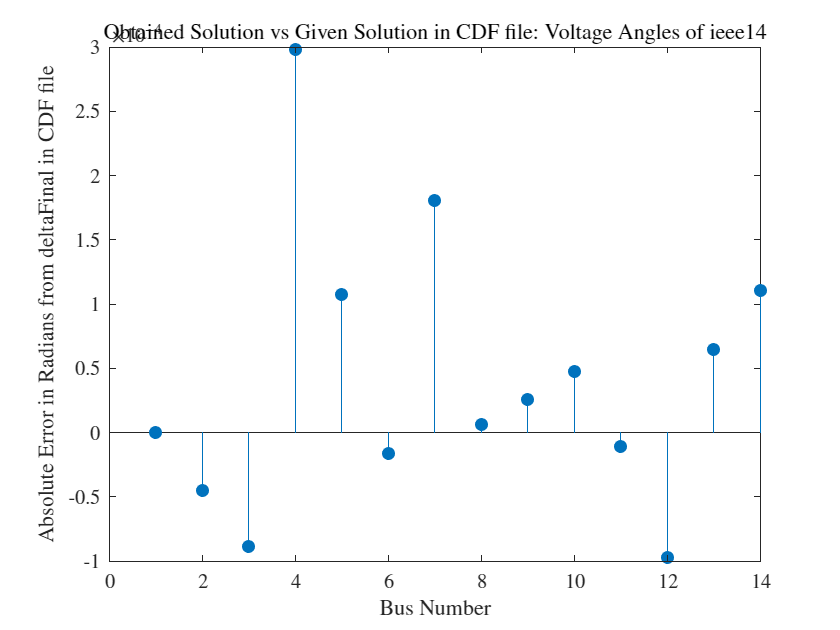


deltaError = delta-(busData.deltaFinal*pi/180);
stem(deltaError, 'filled');
xlabel('Bus Number');
ylabel('Absolute Error in Radians from deltaFinal in CDF file');
title('Obtained Solution vs Given Solution in CDF file: Voltage Angles of ' + systemName);

toc;

Elapsed time is 0.482326 seconds.


# Have a nice day! 